# Analysis of the 25-sec data

## RMSE Comparison

clc
clearvars
close all

exp_num1 = "exp41";

rmse_df_wt = readtable(fullfile(pwd,"log",strcat(exp_num1,"_wt.csv")));
rmse_df_ko = readtable(fullfile(pwd,"log",strcat(exp_num1,"_ko.csv")));

files_wt = categorical(rmse_df_wt.File);
files_ko = categorical(rmse_df_ko.File);
rmse_wt = rmse_df_wt.RMSE;
rmse_ko = rmse_df_ko.RMSE;

figure('Color','w')
subplot(1,2,1)
barh(files_wt,rmse_wt)
grid on
title("WT")
xlabel("RMSE")
set(gca,'FontSize',11,'FontWeight','bold')

subplot(1,2,2)
barh(files_ko,rmse_ko)
grid on
title("MGAT1KO")
xlabel("RMSE")
set(gca,'FontSize',11,'FontWeight','bold')

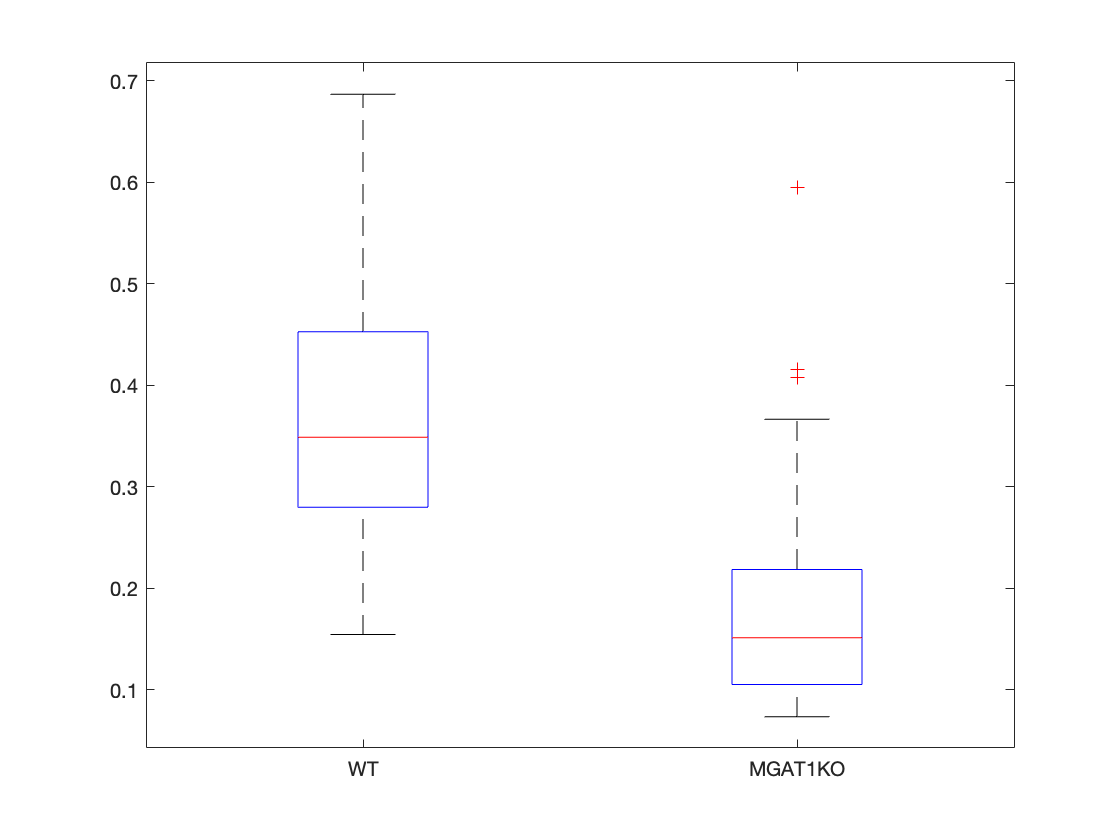

figure('Color','w')
boxplot([rmse_wt,rmse_ko],'Labels',{'WT','MGAT1KO'})

cutoff = quantile([rmse_wt,rmse_ko],0.9)

cutoff =     0.5390    0.3665


files_wt(rmse_wt>cutoff(1))

ans = 3×1 categorical array
     15o26015 
     15n10007 
     15n23012 


files_ko(rmse_ko>cutoff(2))

ans = 3×1 categorical array
     15n03009 
     15n03012 
     15n04007 


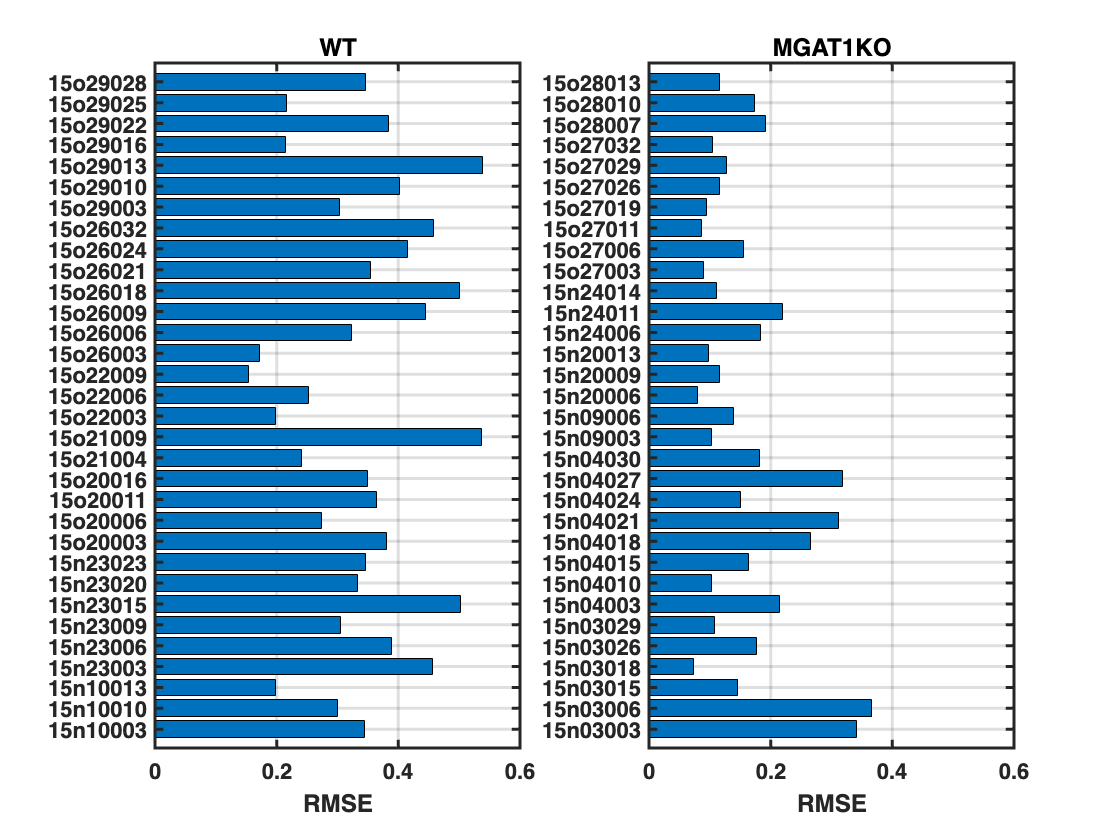

rmv_idx_wt = ismember(files_wt,files_wt(rmse_wt>cutoff(1)));
rmv_idx_ko = ismember(files_ko,files_ko(rmse_ko>cutoff(2)));

figure('Color','w')
subplot(1,2,1)
sub_rmse_df = rmse_df_wt(~rmv_idx_wt,:);
files_wt = string(sub_rmse_df.File);
barh(categorical(sub_rmse_df.File),sub_rmse_df.RMSE)
grid on
title("WT")
xlabel("RMSE")
set(gca,'FontSize',11,'FontWeight','bold','LineWidth',1.5)

subplot(1,2,2)
sub_rmse_df = rmse_df_ko(~rmv_idx_ko,:);
files_ko = string(sub_rmse_df.File);
barh(categorical(sub_rmse_df.File),sub_rmse_df.RMSE)
xlim([0,0.6])
grid on
title("MGAT1KO")
xlabel("RMSE")
set(gca,'FontSize',11,'FontWeight','bold','LineWidth',1.5)

## Kinetics prediction

### Protocol

exp_num = "exp41";
sol_dir = fullfile(pwd,strcat("calib_",exp_num));

current_names = {'iktof','ikslow1','ikslow2','ikss'};
tune_idx = cell(5,1); % iktof, iktos, ikslow1, ikslow2, ikss
tune_idx{1} = [1, 2, 4, 5, 7, 11, 13];
tune_idx{2} = [2, 3];
tune_idx{3} = [1, 2, 4, 5, 9, 10, 11];
tune_idx{4} = [2, 3];
tune_idx{5} = [1, 2, 3, 4];
[mdl_struct,psize] = gen_mdl_struct(current_names,tune_idx);

pdefault = cell(5,1);
pdefault{1} = [33, 15.5, 20, 7, 0.03577, 0.06237, 0.18064, 0.3956, ...
    0.000152, 0.067083, 0.00095, 0.051335, 0.3846];
pdefault{2} = [-1050, 270, 0.0629];
pdefault{3} = [22.5, 45.2, 40.0, 7.7, 5.7, 0.0629, 6.1, 18, 2.058, 803.0, 0.16];
pdefault{4} = [4912, 5334, 0.16];
pdefault{5} = [0.0862, 1235.5, 13.17, 0.0611];

volts = -50:10:50;
ideal_hold_time = 470;
ideal_end_time = 25*1000;
t = 0:ideal_end_time;
pulset = t(ideal_hold_time+1:end);

protocol = cell(6,1);
protocol{1} = -70; % hold_volt
protocol{2} = -91.1; % ek
protocol{4} = t;
protocol{5} = t(1:ideal_hold_time);
protocol{6} = pulset - pulset(1);

## Kinetics prediction

### Prediction loop

atof_wt = NaN(length(files_wt),length(volts));
itof_wt = NaN(length(files_wt),length(volts));
taua_tof_wt = NaN(length(files_wt),length(volts));
taui_tof_wt = NaN(length(files_wt),length(volts));
akslow1_wt = NaN(length(files_wt),length(volts));
ikslow1_wt = NaN(length(files_wt),length(volts));
taua_kslow1_wt = NaN(length(files_wt),length(volts));
taui_kslow1_wt = NaN(length(files_wt),length(volts));
akslow2_wt = NaN(length(files_wt),length(volts));
ikslow2_wt = NaN(length(files_wt),length(volts));
taua_kslow2_wt = NaN(length(files_wt),length(volts));
taui_kslow2_wt = NaN(length(files_wt),length(volts));
akss_wt = NaN(length(files_wt),length(volts));
taua_kss_wt = NaN(length(files_wt),length(volts));

atof_ko = NaN(length(files_ko),length(volts));
itof_ko = NaN(length(files_ko),length(volts));
taua_tof_ko = NaN(length(files_ko),length(volts));
taui_tof_ko = NaN(length(files_ko),length(volts));
akslow1_ko = NaN(length(files_ko),length(volts));
ikslow1_ko = NaN(length(files_ko),length(volts));
taua_kslow1_ko = NaN(length(files_ko),length(volts));
taui_kslow1_ko = NaN(length(files_ko),length(volts));
akslow2_ko = NaN(length(files_ko),length(volts));
ikslow2_ko = NaN(length(files_ko),length(volts));
taua_kslow2_ko = NaN(length(files_ko),length(volts));
taui_kslow2_ko = NaN(length(files_ko),length(volts));
akss_ko = NaN(length(files_ko),length(volts));
taua_kss_ko = NaN(length(files_ko),length(volts));

for i=1:length(files_wt)
    sol_mx = table2array(readtable(fullfile(sol_dir,"wt",strcat(files_wt(i),".xlsx"))));
    sol = gen_sol_vec(sol_mx, mdl_struct, psize);
    
    for j=1:length(volts)
        protocol{3} = volts(j);
        [~,kv] = kv_model(sol,mdl_struct,pdefault,protocol);
        atof_wt(i,j) = kv{1}(1);
        itof_wt(i,j) = kv{1}(2);
        taua_tof_wt(i,j) = kv{1}(3);
        taui_tof_wt(i,j) = kv{1}(4);
        akslow1_wt(i,j) = kv{2}(1);
        ikslow1_wt(i,j) = kv{2}(2);
        taua_kslow1_wt(i,j) = kv{2}(3);
        taui_kslow1_wt(i,j) = kv{2}(4);
        akslow2_wt(i,j) = kv{3}(1);
        ikslow2_wt(i,j) = kv{3}(2);
        taua_kslow2_wt(i,j) = kv{3}(3);
        taui_kslow2_wt(i,j) = kv{3}(4);
        akss_wt(i,j) = kv{4}(1);
        taua_kss_wt(i,j) = kv{4}(2);        
    end
end

for i=1:length(files_ko)
    sol_mx = table2array(readtable(fullfile(sol_dir,"mgat1ko",strcat(files_ko(i),".xlsx"))));
    sol = gen_sol_vec(sol_mx, mdl_struct, psize);

    for j=1:length(volts)
        protocol{3} = volts(j);
        [~,kv] = kv_model(sol,mdl_struct,pdefault,protocol);
        atof_ko(i,j) = kv{1}(1);
        itof_ko(i,j) = kv{1}(2);
        taua_tof_ko(i,j) = kv{1}(3);
        taui_tof_ko(i,j) = kv{1}(4);
        akslow1_ko(i,j) = kv{2}(1);
        ikslow1_ko(i,j) = kv{2}(2);
        taua_kslow1_ko(i,j) = kv{2}(3);
        taui_kslow1_ko(i,j) = kv{2}(4);
        akslow2_ko(i,j) = kv{3}(1);
        ikslow2_ko(i,j) = kv{3}(2);
        taua_kslow2_ko(i,j) = kv{3}(3);
        taui_kslow2_ko(i,j) = kv{3}(4);
        akss_ko(i,j) = kv{4}(1);
        taua_kss_ko(i,j) = kv{4}(2);        
    end
end

### Kinetic prediction

### Plotting

figure('Color','w')
atof = mean(atof_wt,1);
atof_sem = std(atof_wt,0,1)/sqrt(length(files_wt));
errorbar(volts,atof,atof_sem,'-o','Color','blue','MarkerFaceColor','blue','LineWidth',1.5)
hold on
atof = mean(atof_ko,1);
atof_sem = std(atof_ko,0,1)/sqrt(length(files_ko));
errorbar(volts,atof,atof_sem,'--s','Color','red','MarkerFaceColor','red','LineWidth',1.5)
hold off
grid on
ylim([0,1])
xticks(volts)
xlabel("Voltage (mV)")
ylabel("SSA")
legend(["WT","MGAT1KO"],'Location','northwest')
set(gca,'FontSize',11,'FontWeight','bold','LineWidth',1.5)

# Analysis of the 4.5-sec data

## RMSE Comparison

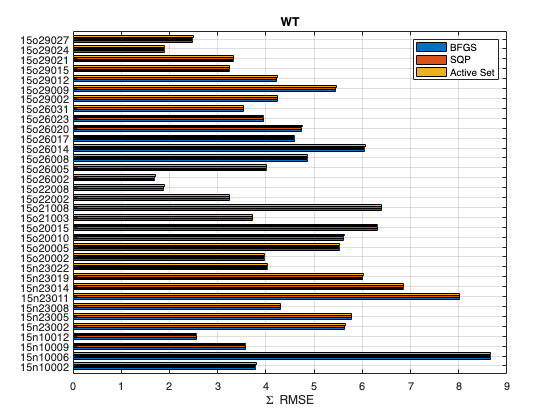

clc
clearvars
close all

exp_num1 = "exp45";
exp_num2 = "exp46";
exp_num3 = "exp47";
group = "wt";

rmse_df1 = readtable(fullfile(pwd,"log",strcat(exp_num1,"_",group,".csv")));
rmse_df2 = readtable(fullfile(pwd,"log",strcat(exp_num2,"_",group,".csv")));
rmse_df3 = readtable(fullfile(pwd,"log",strcat(exp_num3,"_",group,".csv")));
rmse_df_comb = join(rmse_df1,rmse_df2, 'Keys','File');
rmse_df_comb = join(rmse_df_comb,rmse_df3, 'Keys','File');
rmse_df_comb.Properties.VariableNames(2:end) = {'BFGS','SQP','ActiveSet'};
rmse_df_wt = rmse_df_comb;

file_names = categorical(rmse_df_comb.File);
rmse = table2array(rmse_df_comb(:,2:end));

figure('Color','w')
barh(file_names,rmse)
grid on
title("WT")
xlabel("\Sigma RMSE")
legend(["BFGS","SQP","Active Set"])
set(gca,'FontSize',11)

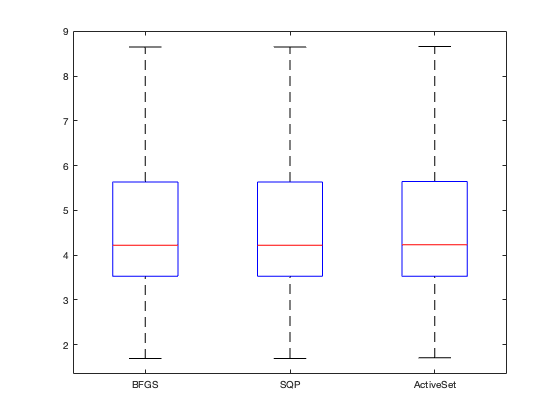

boxplot(table2array(rmse_df_comb(:,2:end)),'Labels',{'BFGS','SQP','ActiveSet'})

cutoff = quantile(table2array(rmse_df_comb(:,2:end)),0.9);
rmse_df_wt.File(rmse_df_wt.BFGS > mean(cutoff))

ans = 3×1 cell array
    {'15n10006'}
    {'15n23011'}
    {'15n23014'}


rmse_df_wt.File(rmse_df_wt.SQP > mean(cutoff))

ans = 3×1 cell array
    {'15n10006'}
    {'15n23011'}
    {'15n23014'}


rmse_df_wt.File(rmse_df_wt.ActiveSet > mean(cutoff))

ans = 3×1 cell array
    {'15n10006'}
    {'15n23011'}
    {'15n23014'}


rmv_idx_wt = ismember(rmse_df_wt.File,rmse_df_wt.File(rmse_df_wt.BFGS > mean(cutoff)));

## Grouped bar graph comparing calibration algorithms (MGAT1KO)

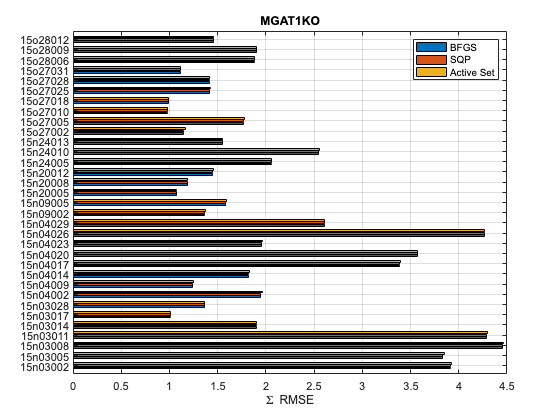

group = "ko";
rmse_df1 = readtable(fullfile(pwd,"log",strcat(exp_num1,"_",group,".csv")));
rmse_df2 = readtable(fullfile(pwd,"log",strcat(exp_num2,"_",group,".csv")));
rmse_df3 = readtable(fullfile(pwd,"log",strcat(exp_num3,"_",group,".csv")));
rmse_df_comb = join(rmse_df1,rmse_df2, 'Keys','File');
rmse_df_comb = join(rmse_df_comb,rmse_df3, 'Keys','File');
rmse_df_comb.Properties.VariableNames(2:end) = {'BFGS','SQP','ActiveSet'};
rmse_df_ko = rmse_df_comb;

file_names = categorical(rmse_df_comb.File);
rmse = table2array(rmse_df_comb(:,2:end));

figure('Color','w')
barh(file_names,rmse)
grid on
title("MGAT1KO")
xlabel("\Sigma RMSE")
legend(["BFGS","SQP","Active Set"])
set(gca, 'FontName','Arial', 'FontSize',11)

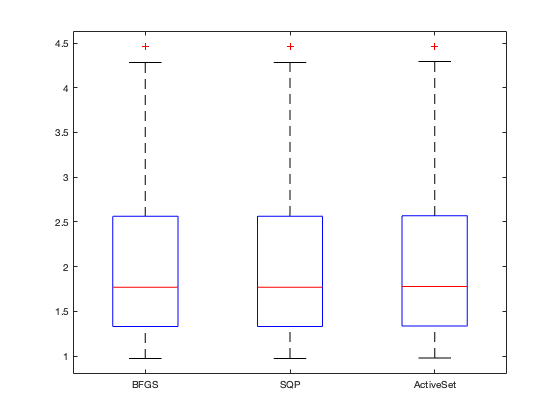

boxplot(table2array(rmse_df_comb(:,2:end)),'Labels',{'BFGS','SQP','ActiveSet'})

cutoff = quantile(table2array(rmse_df_comb(:,2:end)),0.9);
rmse_df_ko.File(rmse_df_ko.BFGS > mean(cutoff))

ans = 3×1 cell array
    {'15n03008'}
    {'15n03011'}
    {'15n04026'}


rmse_df_ko.File(rmse_df_ko.SQP > mean(cutoff))

ans = 3×1 cell array
    {'15n03008'}
    {'15n03011'}
    {'15n04026'}


rmse_df_ko.File(rmse_df_ko.ActiveSet > mean(cutoff))

ans = 3×1 cell array
    {'15n03008'}
    {'15n03011'}
    {'15n04026'}


rmv_idx_ko = ismember(rmse_df_ko.File,rmse_df_ko.File(rmse_df_ko.BFGS > mean(cutoff)));

## New RMSE bar graphs without noisy data points

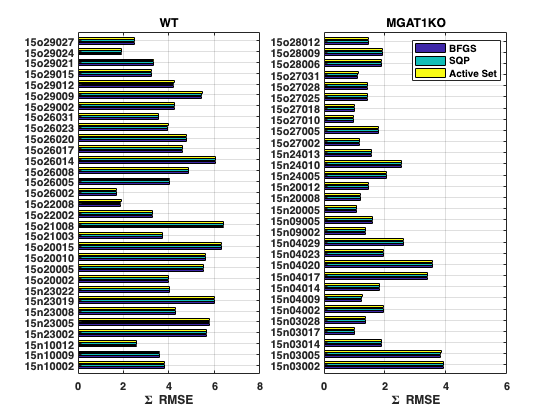

figure('Color','w')
subplot(1,2,1)
sub_rmse_df = rmse_df_wt(~rmv_idx_wt,:);
files_wt = string(sub_rmse_df.File);
rmse = table2array(sub_rmse_df(:,2:end));
b = barh(categorical(files_wt),rmse);
c = parula(3);
for i=1:3
    b(i).FaceColor = c(i,:);
end
grid on
title("WT")
xlabel("\Sigma RMSE")
set(gca,'FontSize',11, 'FontWeight','bold')

subplot(1,2,2)
sub_rmse_df = rmse_df_ko(~rmv_idx_ko,:);
files_ko = string(sub_rmse_df.File);
rmse = table2array(sub_rmse_df(:,2:end));
b = barh(categorical(files_ko),rmse);
for i=1:3
    b(i).FaceColor = c(i,:);
end
xlim([0,6])
grid on
title("MGAT1KO")
xlabel("\Sigma RMSE")
legend(["BFGS","SQP","Active Set"])
set(gca,'FontSize',11, 'FontWeight','bold')

# Kinetics Modeling

## Protocol 4.5-s pulse

exp_num1 = "exp42";
exp_num2 = "exp45";

# Directly comparing model prediction and experimental data

## The 25-sec-pulse data

clc
close all
clearvars

group = "ko";
exp_num = "exp41";
file_name = "15o27006.xlsx";

data_path = fullfile(pwd,"data",strcat(group,"-preprocessed-25s"),file_name);
calib_path = fullfile(pwd,strcat("calib_",exp_num,"_",group),file_name);

current_names = {'iktof', 'ikslow1', 'ikslow2', 'ikss'};
tune_idx1{1} = [1, 2, 4, 5, 7, 11, 13];
tune_idx1{2} = [1, 2, 4, 5, 9, 10, 11];
tune_idx1{3} = [2, 3];
tune_idx1{4} = [1, 2, 3, 4];

% import the experimental data and calibration results
exp_mx = table2array(readtable(data_path));
sol_mx = table2array(readtable(calib_path));
t = exp_mx(:,1);
yksum = exp_mx(:,2);

% protocol
ideal_hold_time = 470;
ideal_end_time = 25*1000;
hold_volt = -70;
volt = 50;
ek = -91.1;

% estimate the critical time points
[~, ideal_hold_idx] = min(abs(t - ideal_hold_time));
[~, ideal_end_idx] = min(abs(t - ideal_end_time));
t = t(1:ideal_end_idx);
yksum = yksum(1:ideal_end_idx);

% time space
time_space = cell(1,3);
time_space{1} = t;
time_space{2} = t(1:ideal_hold_idx);
pulse_t = t(ideal_hold_idx+1:end);
pulse_t_adj = pulse_t - pulse_t(1);
time_space{3} = pulse_t_adj;

% protocol
protocol = cell(1,4);
protocol{1} = hold_volt;
protocol{2} = ek;
protocol{3} = volt;
protocol{4} = time_space;

% prediction from the calibration resukt
[model_info, psize] = gen_mdl_struct(current_names, tune_idx1);
sol = gen_sol_vec(sol_mx, model_info, psize);
[z,yksum_hat,comp_hat] = rmsey(sol, yksum, model_info, protocol);

% figure 1: yksum
figure('Color','w', 'Position',[100,100,560,420])
plot(t,yksum, 'Color','black')
hold on
plot(t, yksum_hat{1}, '--', 'Color','red');
hold off
set(gca, 'XLimSpec','tight')
legend("Experimental Data","Model Prediction")

% figure 2: individual K+ currents
comp_hat = comp_hat{1};
figure('Color','w', 'Position',[600,100,560,420])
plot(t,comp_hat{1})
hold on
plot(t,comp_hat{2})
plot(t,comp_hat{3})
plot(t,comp_hat{4})
hold off
set(gca, 'XLimSpec','tight')
legend("I_{Kto,f}","I_{Kslow1}","I_{Kslow2}","I_{Kss}")

## The 4.5-sec-pulse data

clc
close all 
clearvars

file_group = "wt";
exp_num = "exp45";
file_name = '15n10006.xlsx';
save_dir = strcat('calib_', exp_num);

% import calibration results
calib = table2array(readtable(fullfile(pwd, strcat(save_dir, '_', file_group), file_name)));

%----- Model structure -----%
current_names = {'iktof', 'ikslow1', 'ikslow2', 'ikss'};

tune_idx = cell(5,1); % iktof, iktos, ikslow1, ikslow2, ikss
tune_idx{1} = [1, 2, 4, 5, 7, 11, 13];
tune_idx{2} = [2, 3];
tune_idx{3} = [1, 2, 4, 5, 9, 10, 11];
tune_idx{4} = [2, 3];
tune_idx{5} = [1, 2, 3, 4];

[mdl_struct, psize] = gen_mdl_struct(current_names, tune_idx);
sol = gen_sol_vec(calib, mdl_struct, psize);

pdefault = cell(5,1);
pdefault{1} = [33, 15.5, 20, 7, 0.03577, 0.06237, 0.18064, 0.3956, ...
    0.000152, 0.067083, 0.00095, 0.051335, 0.3846];
pdefault{2} = [-1050, 270, 0.0629];
pdefault{3} = [22.5, 45.2, 40.0, 7.7, 5.7, 0.0629, 6.1, 18, 2.058, 803.0, 0.16];
pdefault{4} = [4912, 5334, 0.16];
pdefault{5} = [0.0862, 1235.5, 13.17, 0.0611];

%----- Protocol & Experimental data -----%
exp_data = table2array(readtable(fullfile(pwd,'mgat1ko_data', ...
    strcat(file_group, '-preprocessed'), file_name)));
t = exp_data(:,1);
yksum = exp_data(:,2:end);

hold_volt = -70;
volts = -30:10:50;
ideal_hold_time = 120;
ideal_end_time = 4.6*1000;
ek = -91.1;

[~, ideal_hold_idx] = min(abs(t - ideal_hold_time));
[~, ideal_end_idx] = min(abs(t - ideal_end_time));
t = t(1:ideal_end_idx);
yksum = yksum(1:ideal_end_idx, :);

protocol = cell(6,1);
protocol{1} = hold_volt;
protocol{2} = ek;
protocol{3} = volts;
protocol{4} = t;
protocol{5} = t(1:ideal_hold_idx);
pulse_t = t(ideal_hold_idx+1:end);
pulse_t_adj = pulse_t - pulse_t(1);
protocol{6} = pulse_t_adj;

%----- Generate yksum_hat -----%
r = obj_rmse(sol, @kcurrent_basic, mdl_struct, pdefault, protocol, yksum);

Unrecognized function or variable 'obj_rmse'.

fprintf('File %s Min RMSE: %f \n', file_name, r)

figure('Color','w')
for i=1:length(volts)
    yksum_i = yksum(:, i);
    ymx = kcurrent_basic(sol, mdl_struct, pdefault, protocol, volts(i));
    yksum_hat1 = sum(ymx,2);

    subplot(3, 3, i)
    plot(t, yksum_i, 'Color','red')
    hold on
    plot(t, yksum_hat1, '--', 'Color','green', 'LineWidth',1.5)
    hold off
    axis tight
    grid on
    title(strcat('Clamp Voltage: ', string(volts(i)), ' mV'));
    xlabel('Time (ms)');
    ylabel('Current (pA/pF)');
    get(gcf,'CurrentAxes');
    set(gca,'YDir','normal');
    set(gca,'LineWidth',1.5);
    set(gca,'GridLineStyle','--')
end
figure('Color','w')
plot(t, yksum(:, 1))
hold on
for i = 2:length(volts)
    plot(t, yksum(:, i))
end
hold off

# Custom functions

function [mdl_struct, psize] = gen_mdl_struct(current_names, tune_idx)
    num_currents = length(current_names);
    
    % index 1
    idx_info1 = cell(1,num_currents);
    for i = 1:num_currents
        switch current_names{i}
            case 'iktof'
                idx_info1{i} = tune_idx{1};
            case 'iktos'
                idx_info1{i} = tune_idx{2};
            case 'ikslow1'
                idx_info1{i} = tune_idx{3};
            case 'ikslow2'
                idx_info1{i} = tune_idx{4};
            case 'ikss'
                idx_info1{i} = tune_idx{5};
        end
    end

    % index 2
    idx_info2 = cell(1,num_currents);
    psize = 0;
    for i = 1: num_currents
        psize_old = psize;
        psize = psize + length(idx_info1{i});
        idx_info2{i} = (1+psize_old):(psize);
    end

    model_info = [current_names; idx_info1; idx_info2];
    field_names = ["name","idx1","idx2"];
    mdl_struct = cell2struct(model_info, field_names, 1);    
end

function sol = gen_sol_vec(sol_mx, model_struct, psize)
    sol = zeros(1, psize);
    for i = 1:length(model_struct)
        running_sol = sol_mx(:, i);
        running_sol = running_sol(~isnan(running_sol));
        sol(model_struct(i).idx2) = running_sol(model_struct(i).idx1);
    end
end

function [ymx, kv] = kv_model(p,mdl_struct,pdefault,protocol)
    current_names = {mdl_struct.name};
    idx_info1 = {mdl_struct.idx1};
    idx_info2 = {mdl_struct.idx2};
    
    % define param_kslow1 first just in case it would be used in advance
    matching_idx = strcmp(current_names, 'ikslow1');
    param_kslow1 = pdefault{3};
    if any(matching_idx)
        param_kslow1(idx_info1{matching_idx}) = p(idx_info2{matching_idx});
    end

    ymx = zeros(length(protocol{4}),length(current_names));
    kv = cell(length(current_names),1);
    for i = 1:length(current_names)
        switch current_names{i}
            case 'iktof'
                param = pdefault{1};
                param(idx_info1{i}) = p(idx_info2{i});
                [ymx(:,i),kv{i}] = iktof(param, protocol);
            case 'iktos'
                num_param = 11;
                shared_idx = [1:7,9];
                uniq_idx = setdiff(1:num_param, shared_idx);

                param = NaN(num_param,1);
                param(shared_idx) = param_kslow1(shared_idx);
                uniq_param = pdefault{2};
                uniq_param(idx_info1{i}) = p(idx_info2{i});
                param(uniq_idx) = uniq_param;
                [ymx(:,i),kv{i}] = iktos(param, protocol);
            case 'ikslow1'
                [ymx(:,i),kv{i}] = ikslow1(param_kslow1, protocol);
            case 'ikslow2'
                num_param = 11;
                shared_idx = [1:7,9];
                uniq_idx = setdiff(1:num_param, shared_idx);

                param = NaN(num_param,1);
                param(shared_idx) = param_kslow1(shared_idx);
                uniq_param = pdefault{4};
                uniq_param(idx_info1{i}) = p(idx_info2{i});
                param(uniq_idx) = uniq_param;
                [ymx(:,i),kv{i}] = ikslow2(param, protocol);
            case 'ikss'
                num_param = 7;
                shared_idx1 = 1:3;
                shared_idx2 = [1,3,4];
                uniq_idx = setdiff(1:num_param, shared_idx1);

                param = NaN(num_param,1);
                param(shared_idx1) = param_kslow1(shared_idx2);
                uniq_param = pdefault{5};
                uniq_param(idx_info1{i}) = p(idx_info2{i});
                param(uniq_idx) = uniq_param;
                [ymx(:,i),kv{i}] = ikss(param, protocol);
        end
    end    
end

function [y,kv_pulse] = iktof(p, protocol)
    gmax = p(13);
    act0 = 0.4139033547e-02;
    inact0 = 0.9999623535e+00;
    
    holdv = protocol{1};
    ek = protocol{2};
    volt = protocol{3};
    t = protocol{4};
    holdt = protocol{5};
    hold_idx = length(holdt);
    pulset = protocol{6};
    
    y = zeros(length(t),1);

    % current equation at holding volt
    kv_hold = iktof_kinetic_variables(p, holdv);
    act_hold = hh_model(holdt, act0, kv_hold(1), kv_hold(3));
    inact_hold = hh_model(holdt, inact0, kv_hold(2), kv_hold(4));
    y(1:hold_idx) = gmax.*(act_hold.^3).*(inact_hold).*(holdv-ek);

    % current equation at pulse volt
    kv_pulse = iktof_kinetic_variables(p, volt);
    act_pulse = hh_model(pulset, act0, kv_pulse(1), kv_pulse(3));
    inact_pulse = hh_model(pulset, inact0, kv_pulse(2), kv_pulse(4));
    y((hold_idx+1):end) = gmax.*(act_pulse.^3).*(inact_pulse).*(volt-ek);    
end

function [y,kv_pulse] = iktos(p,protocol)
    gmax = p(11);
    act0 = 0.5091689794e-03;
    inact0 = 0.9980927689e+00;

    holdv = protocol{1};
    ek = protocol{2};
    volt = protocol{3};
    t = protocol{4};
    holdt = protocol{5};
    hold_idx = length(holdt);
    pulset = protocol{6};
    
    y = zeros(length(t),1);

    % current equation at holding
    kv_hold = rectifier_kinetic_variables(p, holdv);
    act_hold = hh_model(holdt, act0, kv_hold(1), kv_hold(3));
    inact_hold = hh_model(holdt, inact0, kv_hold(2), kv_hold(4));
    y(1:hold_idx) = gmax.*(act_hold).*(inact_hold).*(holdv - ek);
    
    % current equation at pulse voltage
    kv_pulse = rectifier_kinetic_variables(p, volt);
    act_pulse = hh_model(pulset, act0, kv_pulse(1), kv_pulse(3));
    inact_pulse = hh_model(pulset, inact0, kv_pulse(2), kv_pulse(4));
    y((hold_idx+1):end) = gmax.*(act_pulse).*(inact_pulse).*(volt - ek);    
end

function [y,kv_pulse] = ikslow1(p,protocol)
    gmax = p(11);
    act0 = 0.5091689794e-03;
    inact0 = 0.9980927689;
    
    holdv = protocol{1};
    ek = protocol{2};
    volt = protocol{3};
    t = protocol{4};
    holdt = protocol{5};
    hold_idx = length(holdt);
    pulset = protocol{6};

    y = zeros(length(t),1);

    % current equation at holding 
    kv_hold = rectifier_kinetic_variables(p, holdv);
    act_hold = hh_model(holdt, act0, kv_hold(1), kv_hold(3));
    inact_hold = hh_model(holdt, inact0, kv_hold(2), kv_hold(4));        
    y(1:hold_idx) = (gmax).*(act_hold).*(inact_hold).*(holdv-ek);

    % current equation at pulse voltage
    kv_pulse = rectifier_kinetic_variables(p, volt);
    act_pulse = hh_model(pulset, act0, kv_pulse(1), kv_pulse(3));
    inact_pulse = hh_model(pulset, inact0, kv_pulse(2), kv_pulse(4));
    y((hold_idx+1):end) = (gmax).*(act_pulse).*(inact_pulse).*(volt-ek);
end

function [y,kv_pulse] = ikslow2(p,protocol)
    gmax = p(11); 
    act0 = 0.5091689794e-03;
    inact0 = 0.9980927689;

    holdv = protocol{1};
    ek = protocol{2};
    volt = protocol{3};
    t = protocol{4};
    holdt = protocol{5};
    hold_idx = length(holdt);
    pulset = protocol{6};
    
    y = zeros(length(t),1);

    % current equation at holding
    kv_hold = rectifier_kinetic_variables(p, holdv);
    act_hold = hh_model(holdt, act0, kv_hold(1), kv_hold(3));
    inact_hold = hh_model(holdt, inact0, kv_hold(2), kv_hold(4));
    y(1:hold_idx) = gmax.*(act_hold).*(inact_hold).*(holdv - ek);

    % current equation at pulse voltage
    kv_pulse = rectifier_kinetic_variables(p, volt);
    act_pulse = hh_model(pulset, act0, kv_pulse(1), kv_pulse(3));
    inact_pulse = hh_model(pulset, inact0, kv_pulse(2), kv_pulse(4));
    y((hold_idx+1):end) = gmax.*(act_pulse).*(inact_pulse).*(volt - ek);
end

function [y,kv_pulse] = ikss(p,protocol)
    gmax = p(7);
    act0 = 0.5091689794e-03;

    holdv = protocol{1};
    ek = protocol{2};
    volt = protocol{3};
    t = protocol{4};
    holdt = protocol{5};
    hold_idx = length(holdt);
    pulset = protocol{6};
    
    y = zeros(length(t),1);

    % current equation at holding
    kv_hold = ikss_kinetic_variables(p, holdv);
    act_hold = hh_model(holdt, act0, kv_hold(1), kv_hold(2));
    y(1:hold_idx) = gmax.*act_hold.*(holdv - ek);

    % current equation at pulse voltage
    kv_pulse = ikss_kinetic_variables(p, volt);
    act_pulse = hh_model(pulset, act0, kv_pulse(1), kv_pulse(2));
    y((hold_idx+1):end) = gmax.*act_pulse.*(volt - ek);
end

function kv = iktof_kinetic_variables(p, V)
    kv = NaN(8,1);
    
    alpha1 = p(7).*exp(p(5).*(V+p(1)));
    beta1 = p(8).*exp(-p(6).*(V+p(1)));
    
    alpha2_temp1 = p(9).*exp((V+p(2))./(-1.0.*p(4)));
    alpha2_temp2 = p(10).*exp((V+p(2)+p(3))./(-1.0.*p(4)));
    alpha2 = alpha2_temp1./(1.0+alpha2_temp2);

    beta2_temp1 = p(11).*exp((V+p(2)+p(3))./p(4));
    beta2_temp2 = p(12).*exp((V+p(2)+p(3))./p(4));
    beta2 = beta2_temp1./(1.0+beta2_temp2);

    kv(1) = alpha1./(alpha1+beta1);
    kv(2) = alpha2./(alpha2+beta2);
    kv(3) = 1./(alpha1+beta1);
    kv(4) = 1./(alpha2+beta2);
    kv(5) = alpha1;
    kv(6) = beta1;
    kv(7) = alpha2;
    kv(8) = beta2;
end

function kv = rectifier_kinetic_variables(p, V)
    kv = NaN(4,1);
    kv(1) = 1.0./(1.0+exp(-(p(1)+V)./p(4))); % ass
    kv(2) = 1.0./(1.0+exp((p(2)+V)./p(5))); % iss
    kv(3) = p(7)./(exp(p(6)*(V+p(3))) + exp(-p(6)*(V+p(3))))+p(9); % taua
    kv(4) = p(10) - p(8)./(1.0+exp((p(2)+V)./p(5))); % taui
end

function kv = ikss_kinetic_variables(p, V)
    kv = NaN(2,1);
    kv(1) = 1.0./(1.0+exp(-(p(1)+V)./p(3)));
    kv(2) = p(5)./(exp(p(4)*(V+p(2))) + exp(-p(4)*(V+p(2)))) + p(6);
end

function y = hh_model(t, ss0, ss, tau)
    y = ss - (ss - ss0).*exp(-t./tau);
end